# Figure 4 on events

org = Org;
org.init;

figure;
org.correlogram('signal_density', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations signal_density vs. asymp_ratio: adj. R^2 = 0.308
Pearson: -0.620, p = 5.568617e-02, n.s
Spearman: -0.297, p = 4.069502e-01, n.s
Kendall: -0.244, p = 3.807198e-01, n.s


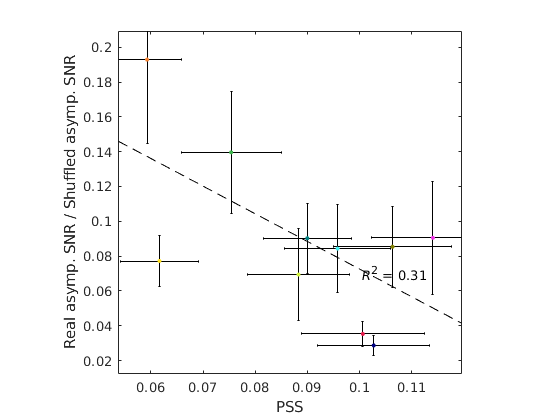

xlabel PSS
%ylabel(sprintf('SNR-asymptote ensemble\n____________________________________\nSNR-asymptote ensemble (shuff.)'));
ylabel 'Real asymp. SNR / Shuffled asymp. SNR'
axis square
Utils.printto('events_figs/f4_events', 'pss_snr_ratio_correlation.pdf');

figure;
org.correlogram('dmu_ipr', 'inv_asymp_ratio', true, true, true);

Using only 72 out of 110 sessions
Mouse-aggregated correlations dmu_ipr vs. inv_asymp_ratio: adj. R^2 = 0.836
Pearson: 0.924, p = 1.324509e-04, ***
Spearman: 0.758, p = 1.592083e-02, *
Kendall: 0.556, p = 2.860946e-02, *


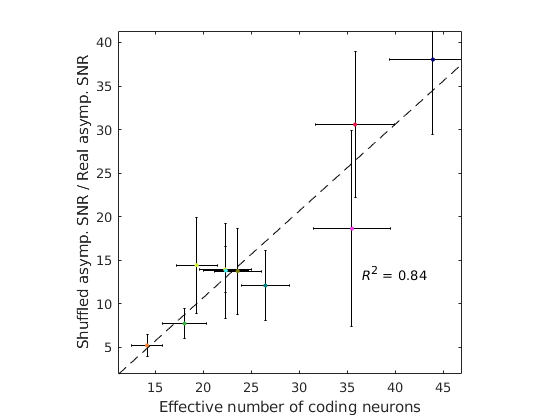

xlabel 'Effective number of coding neurons'
ylabel 'Shuffled asymp. SNR / Real asymp. SNR'
axis square
Utils.printto('events_figs/f4_events', 'number_snr_ratio_correlation.pdf');

Passes a path analysis with number of neurons:

fitlm([zscore(org.sess_prop.num_neurons), zscore(org.sess_prop.dmu_ipr)], zscore(org.sess_prop.inv_asymp_ratio))

ans = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    4.2968e-16     0.05739    7.4871e-15             1
    x1               -0.10025    0.072991       -1.3734        0.1725
    x2                0.86028    0.072991        11.786    4.7052e-21


Number of observations: 110, Error degrees of freedom: 107
Root Mean Squared Error: 0.602
R-squared: 0.644,  Adjusted R-Squared: 0.638
F-statistic vs. constant model: 96.9, p-value = 9.55e-25

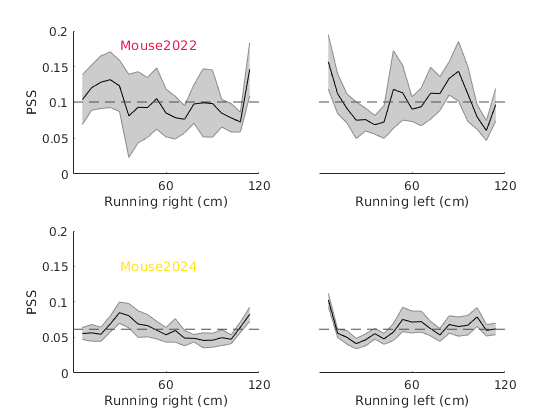

figure;

subplot(2,2,1);
mouse_name = 'Mouse2022';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax=gca;
ax.XTick = [10 20];
ax.XTickLabel={'60','120'};
ylim([0 0.2]);
ylabel PSS
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.18, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,2);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.2]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'



subplot(2,2,3);
mouse_name = 'Mouse2024';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax = gca;
ax.XTick = [10 20];
ax.XTickLabel = {'60', '120'};
ylim([0 0.2]);
ylabel PSS
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.15, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,4);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.2]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'
Utils.printto('events_figs/f4_events', 'pss_by_bin.pdf');

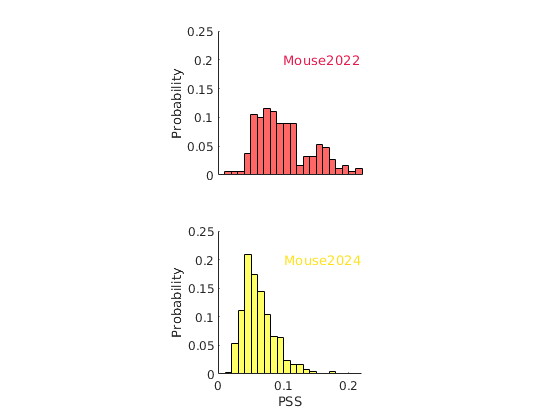


%%
figure;
x_ = org.mouse_all_sess('signal_density', {'Mouse2022', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('signal_density', {'Mouse2024', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 0.01;
subplot(2,1,1);
histogram(x_, 'BinWidth', bin_width, 'FaceColor', 'r', 'Normalization', 'probability');
ylabel 'Probability'
axis square;
ax1 = gca;
ax1.Box = 'off';
ax1.XTick = [];
m_color = DecodeTensor.mcolor({'Mouse2022'});
m_color = m_color{1};
text(0.1, 0.2, 'Mouse2022', 'Color', m_color);

subplot(2,1,2);
histogram(y_, 'BinWidth', bin_width, 'FaceColor', 'y', 'Normalization', 'probability');
xlabel 'PSS'
ylabel 'Probability'
axis square;
ax2 = gca;
ax2.Box = 'off';
m_color = DecodeTensor.mcolor({'Mouse2024'});
m_color = m_color{1};
text(0.1, 0.2, 'Mouse2024', 'Color', m_color);
linkaxes([ax1 ax2]);
Utils.printto('events_figs/f4_events', 'pss_histograms.pdf');

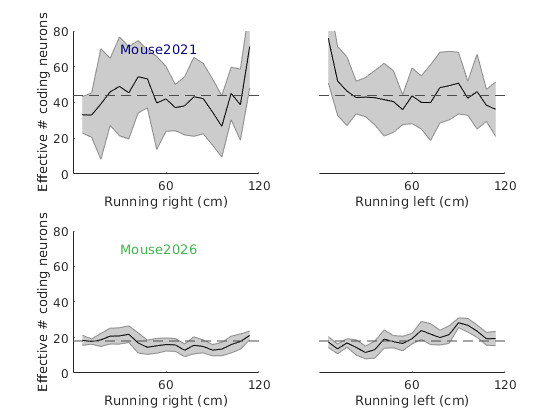

figure;

subplot(2,2,1);
mouse_name = 'Mouse2021';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax=gca;
ax.XTick = [10 20];
ax.XTickLabel={'60','120'};
ylim([0 80]);
ylabel 'Effective # coding neurons'
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 70, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,2);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 80]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'



subplot(2,2,3);
mouse_name = 'Mouse2026';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax = gca;
ax.XTick = [10 20];
ax.XTickLabel = {'60', '120'};
ylim([0 80]);
ylabel 'Effective # coding neurons'
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 70, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,4);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 80]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'
Utils.printto('events_figs/f4_events', 'number_by_bin.pdf');

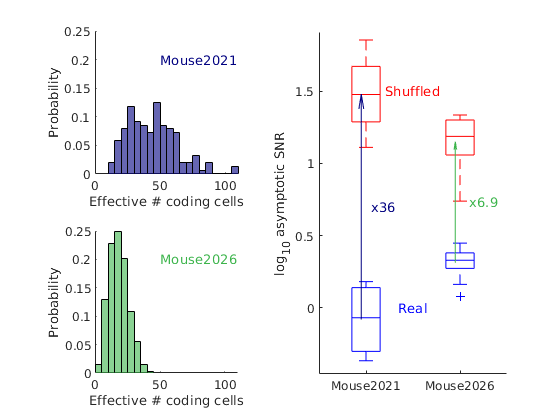


%%
figure;
x_ = org.mouse_all_sess('dmu_ipr', {'Mouse2021', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('dmu_ipr', {'Mouse2026', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 5;
subplot(2,2,1);

m_color = DecodeTensor.mcolor({'Mouse2021'});
m_color = m_color{1};
text(0.1*500, 0.2, 'Mouse2021', 'Color', m_color); hold on;
histogram(x_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
xlabel 'Effective # coding cells'
ylabel 'Probability'
axis square;
ax1 = gca;
ax1.Box = 'off';
%ax1.XTick = [];


subplot(2,2,3);
m_color = DecodeTensor.mcolor({'Mouse2026'});
m_color = m_color{1};
text(0.1*500, 0.2, 'Mouse2026', 'Color', m_color); hold on;
histogram(y_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
xlabel 'Effective # coding cells'
ylabel 'Probability'
axis square;
ax2 = gca;
ax2.Box = 'off';
linkaxes([ax1 ax2]);

subplot(2,2, [2 4]);
get_prop = @(p, m) org.sess_prop.(p)(strcmp(org.mouse, m));
get_mouse = @(m) org.mouse(strcmp(org.mouse, m));

boxplot(log10([get_prop('asymp_snr', 'Mouse2021');...
    get_prop('asymp_snr', 'Mouse2026')]),...
    [get_mouse('Mouse2021'), get_mouse('Mouse2026')],...
    'Colors', 'b', 'Symbol', '+');
hold on;
boxplot(log10([get_prop('asymp_snr_shuf', 'Mouse2021');...
    get_prop('asymp_snr_shuf', 'Mouse2026')]),...
    [get_mouse('Mouse2021'), get_mouse('Mouse2026')],...
    'Colors', 'r', 'Symbol', '+');
ylabel 'log_{10} asymptotic SNR'
text(1.5, 0, 'Real', 'Color', 'b', 'HorizontalAlignment','center');
text(1.5, 1.5, 'Shuffled', 'Color', 'r', 'HorizontalAlignment','center');

drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:} );
m_color = DecodeTensor.mcolor({'Mouse2021'});
m_color = m_color{1};
b = mean(log10(get_prop('asymp_snr', 'Mouse2021')));
t = mean(log10(get_prop('asymp_snr_shuf', 'Mouse2021')));
drawArrow([1 1]-0.05,[b t], 'Color', m_color);
text(1 + 0.05, (b+t)/2, sprintf('x%.2g', 10^(t-b)), 'Color', m_color);

m_color = DecodeTensor.mcolor({'Mouse2026'});
m_color = m_color{1};
b = mean(log10(get_prop('asymp_snr', 'Mouse2026')));
t = mean(log10(get_prop('asymp_snr_shuf', 'Mouse2026')));
drawArrow([2 2]-0.05,[b t], 'Color', m_color);
text(2 + 0.1, (b+t)/2, sprintf('x%.2g', 10^(t-b)), 'Color', m_color);

set(gca, 'Box', 'off');

Utils.printto('events_figs/f4_events', 'number_histograms.pdf');

## Supplementary: Distributions of PSS or effective # per mouse

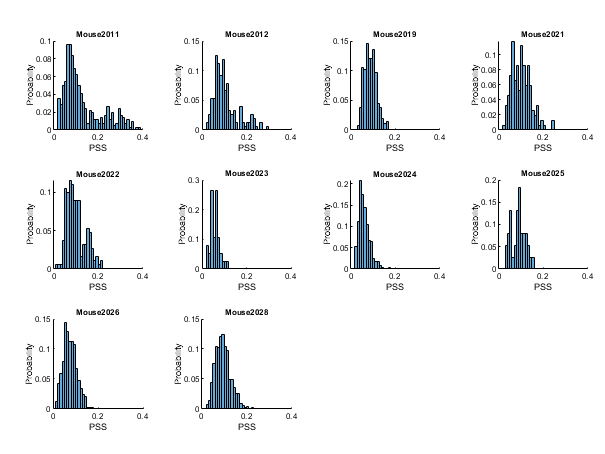

m = SessManager.highqual_mice;

p = Pub(16, 12, 'rows', 3, 'columns', 4, 'hspacing', 0.08, 'vspacing', 0.11);

for m_i = 1:numel(m)
    p.panel(m_i, 'xlab', 'PSS', 'ylab', 'Probability', 'letter', '', 'title', m{m_i});
    
    my_mouse = m{m_i};
    
    PSS = org.mouse_all_sess('signal_density', {my_mouse, 'restrict'});
    PSS = PSS(:);
    PSS(isnan(PSS)) = [];
    
    bin_width = 0.01;
    histogram(PSS, 'BinWidth', bin_width, 'Normalization', 'probability');
    xlim([0 0.4]);
    axis square;
    ax2 = gca;
    ax2.Box = 'off';
end
p.format;
Utils.printto('events_figs/f4_supplements', 'PSS_histograms_per_mouse.pdf');

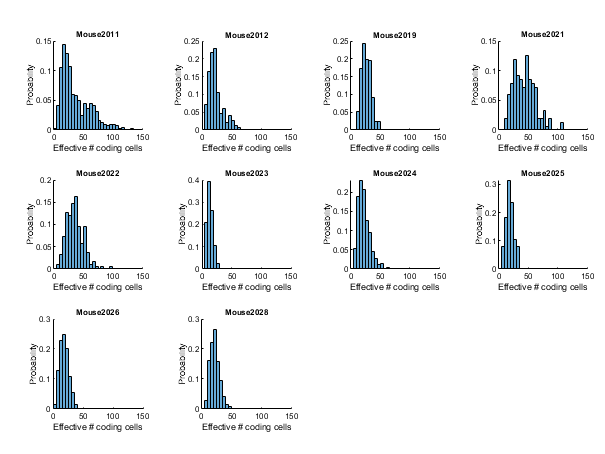

m = SessManager.highqual_mice;

p = Pub(16, 12, 'rows', 3, 'columns', 4, 'hspacing', 0.08, 'vspacing', 0.11);

for m_i = 1:numel(m)
    p.panel(m_i, 'xlab', 'Effective # coding cells', 'ylab', 'Probability', 'letter', '', 'title', m{m_i});
    
    my_mouse = m{m_i};
    
    EFN = org.mouse_all_sess('dmu_ipr', {my_mouse, 'restrict'});
    EFN = EFN(:);
    EFN(isnan(EFN)) = [];
    
    bin_width = 5;
    histogram(EFN, 'BinWidth', bin_width, 'Normalization', 'probability');
    xlim([0 150]);
    axis square;
    ax2 = gca;
    ax2.Box = 'off';
end
p.format;
Utils.printto('events_figs/f4_supplements', 'effective_number_histograms_per_mouse.pdf');

Correlation between the asymp_snr ratio and variance of RF shapes

p = Pub(13,6, 'rows', 1, 'columns', 2);
p.panel(1, 'xlab', 'Var(RF-slope^2)', 'ylab', 'Asymp. SNR ratio (real/shuffled)');
org.correlogram('signal_var', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 71 out of 110 sessions
Mouse-aggregated correlations signal_var vs. asymp_ratio: adj. R^2 = 0.365
Pearson: 0.660, p = 3.795920e-02, *
Spearman: 0.552, p = 1.042978e-01, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


p.panel(2, 'xlab', 'Var(RF-slope^2)', 'ylab', 'Asymp. SNR ratio (shuffled/real)');
org.correlogram('signal_var', 'inv_asymp_ratio', true, true, true);

Using only 71 out of 110 sessions
Mouse-aggregated correlations signal_var vs. inv_asymp_ratio: adj. R^2 = 0.478
Pearson: -0.732, p = 1.610566e-02, *
Spearman: -0.479, p = 1.660580e-01, n.s
Kendall: -0.422, p = 1.083135e-01, n.s


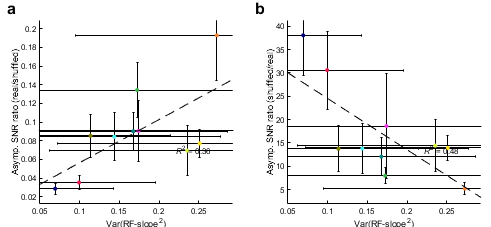

p.format;
Utils.printto('events_figs/f4_supplements', 'var_rf.pdf');

mus = cellfun(@(x)mean(cellfun(@mean, x)), org.fetch('mus'));
mus_c = cellfun(@(x)1.96*sem(cellfun(@mean, x)), org.fetch('mus'));
f = SessManager.highqual_filt_from_usable;
asymp_ratio = org.sess_prop.asymp_ratio;
asymp_ratio_c = org.sess_prop_conf.asymp_ratio;

fitlm(mus(f), asymp_ratio(f))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.14106    0.031354     4.4991    2.6038e-05
    x1             -0.10653     0.06065    -1.7565       0.08332


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.043
R-squared: 0.0416,  Adjusted R-Squared: 0.0281
F-statistic vs. constant model: 3.09, p-value = 0.0833

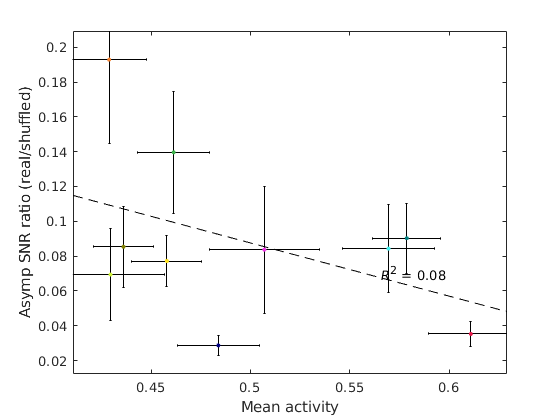

m = org.mouse;
figure;
PanelGenerator.plot_regress_averaged(mus(f), asymp_ratio(f), mus_c(f), asymp_ratio_c(f), m(f), 'k', 'dotsize', 10);
xlabel 'Mean activity'
ylabel 'Asymp SNR ratio (real/shuffled)'
Utils.printto('events_figs/f4_supplements', 'mean_activity_vs_asymp_ratio.pdf');

## Repeating the asymp SNR ratio to effective number correlation per bin

%{
my_mice = SessManager.highqual_mice;
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [eff_m{m_i}, eff_s{m_i}] = org.mouse_by_bins('dmu_ipr', {my_mouse, 'restrict'});
    [asr_m{m_i}, asr_s{m_i}] = org.mouse_by_bins('inv_asymp_ratio', {my_mouse, 'restrict'});
end

for b_i = 1:40
    fprintf('Bin index %d\n', b_i);
    if isnan(eff_m{1}(b_i))
        continue;
    end
    bin_eff = cellfun(@(x)x(b_i), eff_m);
    bin_asr = cellfun(@(x)x(b_i), asr_m);
    %Org.corr_check(bin_eff, bin_asr);
    [p,pp,s,sp,k,kp,adjr2] = Org.corr_check(bin_eff, bin_asr);
    fprintf('Mouse-aggregated correlations %s vs. %s: adj. R^2 = %.3f\n', var1, var2, adjr2);
    fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));
    fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));
    fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));
end
%}